# Trabalho Computacional de Sistemas Realimentados

### Componentes do grupo: Amanda S. Bassani e João Paulo B. da Rocha

clear
clc
close all
format shortG
format compact

syms x
N = 11;

## Projeto 1.1

Uma empilhadeira eletro-hidráulica potente pode ser usada para erguer material paletizado pesando várias toneladas no topo de uma plataforma de 10 m em um canteiro de obras. O sistema de controle com realimentação negativa possui uma função de transferência em malha aberta (atuador+planta+sensor) dada por:


$$G_{MA} =\frac{s^2+Ns+10}{s^2(s+\sqrt{N})}$$
 

Para encontrar o controlador para que a resposta ao degrau seja a mais rápida possível, com o menor sobressinal e erro em regima à rampa igual a zero, primeiro deve-se obter a função de malha aberta e desenhar o lugar das raízes:

**Função de malha aberta inicial**

t=0:.001:1; % tempo para simulação do projeto 1.1

nump = [1 N 10];
denp = conv([1 0 0],[1 sqrt(N)]);
gp = tf(nump,denp);
zpk(gp)

ans =
 
  (s+10) (s+1)
  -------------
  s^2 (s+3.317)
 
Continuous-time zero/pole/gain model.



### Condições de Projeto

**Lugar das Raízes para ganho proporcional**

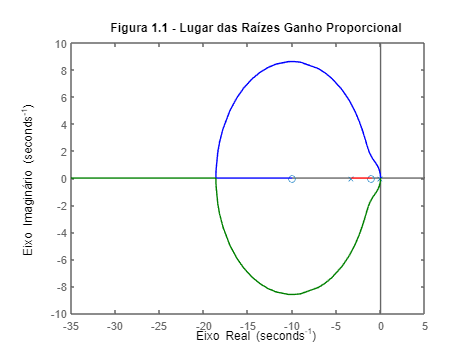

figure
rlocus(gp)
title('Figura 1.1 - Lugar das Raízes Ganho Proporcional');
ylabel('Eixo Imaginário')
xlabel('Eixo Real') 

Como o sistema já apresenta 2 pólos na origem (sistema do Tipo 2), da teoria de controle sabe-se que não é necessário utilizar um controlador PI para atender a especificação de erro a entrada em rampa igual a zero, pois a própria planta já atende a essa especificação. Restando avaliar o melhor controlador (PD ou P).

O ganho proporcional avaliado no lugar das raízes acima, mostra a variação da resposta com o aumento do ganho. Considerando as premissas de projeto de resposta ao degrau mais rápida e o menor sobresinal, faz-se necessário uma avaliação mais profunda e detalhada entre os controladores P e PD.

Nos controladores Proporcionais, a medida que aumentamos o ganho (K ou Kp) o tempo de subida diminui, e o sobresinal tende a aumentar. Avaliando o Lugar das Raízes da função de malha aberta da planta, o tempo de subida de fato diminuiu entretanto o sobresinal também diminuiu. Tal efeito é característica da dominância dos polos, e com isso o ganho proporcional teve um comportamento de queda da sobreelevação.

Podemos avaliar esse comportamento plotando a resposta para diferentes ganhos e avaliando o gráfico abaixo já conseguimos concluir esse comportamento.

**Respostas ao degrau para ganho proporcional**

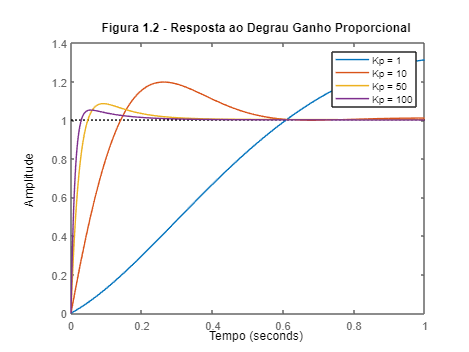

gk1 = feedback(gp,1);
gk2 = feedback(10*gp,1);
gk3 = feedback(50*gp,1);
gk4 = feedback(100*gp,1);

figure
step(gk1,t); 

hold on
step(gk2,t);
step(gk3,t);
step(gk4,t);
title('Figura 1.2 - Resposta ao Degrau Ganho Proporcional');
xlabel('Tempo');
legend('Kp = 1','Kp = 10','Kp = 50','Kp = 100');

Por meio da função rltool é possível perceber que o tempo de subida, o sobressinal e o tempo de estabelecimento diminuem com o aumento do ganho Kp. Porém, adicionando um controlador derivativo junto ao poporcional é esperado que o tempo de resposta diminua, e a sobreelevação também, assim como a oscilação (caso haja alguma). Serão adotados diferentes valores de Kp e Kd para que os resultados sejam comparados.

**Simulação dos parâmetros para controlador PD**

Escolhe-se Kp = 10, com Kd variando entre 1, 3 e 5:

Kp = 10;
gg(1)=Kp*gp;
gmf(1)=feedback(gg(1),1);
y1=step(gmf(1),t);
% Projetando PD para menor sobressinal e para deixar o sistema mais rápido

**Função de malha aberta linha para parâmetros controlador PD  **

num_sym = x*poly2sym(nump);
den_sym = poly2sym(denp)+poly2sym(nump)*Kp;
gma = tf(sym2poly(num_sym),sym2poly(den_sym))

gma =
 
       s^3 + 11 s^2 + 10 s
  -----------------------------
  s^3 + 13.32 s^2 + 110 s + 100
 
Continuous-time transfer function.



**Lugar das Raízes a partir da GMA linha**

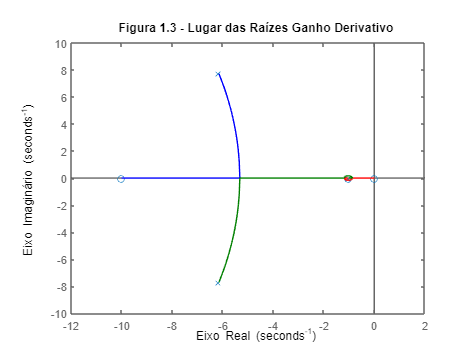

figure
rlocus(gma)
title('Figura 1.3 - Lugar das Raízes Ganho Derivativo');
ylabel('Eixo Imaginário')
xlabel('Eixo Real') 


% Simulando o controlador PD em malha fechada p/ diferentes valores de Kd
Kd = 1;
gc=tf([Kd Kp],1);
gg(2)=gc*gp;
gmf(2)=feedback(gg(2),1);
y2=step(gmf(2),t);

Kd = 3;
gc=tf([Kd Kp],1);
gg(3)=gc*gp;
gmf(3)=feedback(gg(3),1);
y3=step(gmf(3),t);

Kd = 5;
gc=tf([Kd Kp],1);
gg(4)=gc*gp;
gmf(4)=feedback(gg(4),1);
y4=step(gmf(4),t);

Escolhe-se Kp = 100, com Kd variando entre 1, 3 e 5: Repetindo os passos anteriores 

Kp = 100;
gg(5)=Kp*gp;
gmf(5)=feedback(gg(5),1);
y5=step(gmf(5),t);

% Projetando PD para menor sobressinal e para deixar o sistema mais rápido

num_sym = x*poly2sym(nump);
den_sym = poly2sym(denp)+poly2sym(nump)*Kp;
gma = tf(sym2poly(num_sym),sym2poly(den_sym));

% figure
% rlocus(gma) 

% Simulando o controlador PD em malha fechada p/ diferentes valores de Kd
Kd = 1;
gc=tf([Kd Kp],1);
gg(6)=gc*gp;
gmf(6)=feedback(gg(6),1);
y6=step(gmf(6),t);

Kd = 3;
gc=tf([Kd Kp],1);
gg(7)=gc*gp;
gmf(7)=feedback(gg(7),1);
y7=step(gmf(7),t);

Kd = 5;
gc=tf([Kd Kp],1);
gg(8)=gc*gp;
gmf(8)=feedback(gg(8),1);
y8=step(gmf(8),t);

Escolhe-se Kp = 1000, com Kd variando entre 1, 3 e 5: Repetindo os passos anteriores 

Kp = 1000;
gg(9)=Kp*gp;
gmf(9)=feedback(gg(9),1);
y9=step(gmf(9),t);

% Projetando PD para menor sobressinal e para deixar o sistema mais rápido

num_sym = x*poly2sym(nump);
den_sym = poly2sym(denp)+poly2sym(nump)*Kp;
gma = tf(sym2poly(num_sym),sym2poly(den_sym));

% figure
% rlocus(gma) 
% Simulando o controlador PD em malha fechada p/ diferentes valores de Kd
Kd = 1;
gc=tf([Kd Kp],1);
gg(10)=gc*gp;
gmf(10)=feedback(gg(10),1);
y10=step(gmf(10),t);

Kd = 3;
gc=tf([Kd Kp],1);
gg(11)=gc*gp;
gmf(11)=feedback(gg(11),1);
y11=step(gmf(11),t);

Kd = 5;
gc=tf([Kd Kp],1);
gg(12)=gc*gp;
gmf(12)=feedback(gg(12),1);
y12=step(gmf(12),t);

### Resultados

Representação gráfica dos resultados das simulações e seus parâmetros tabulados.

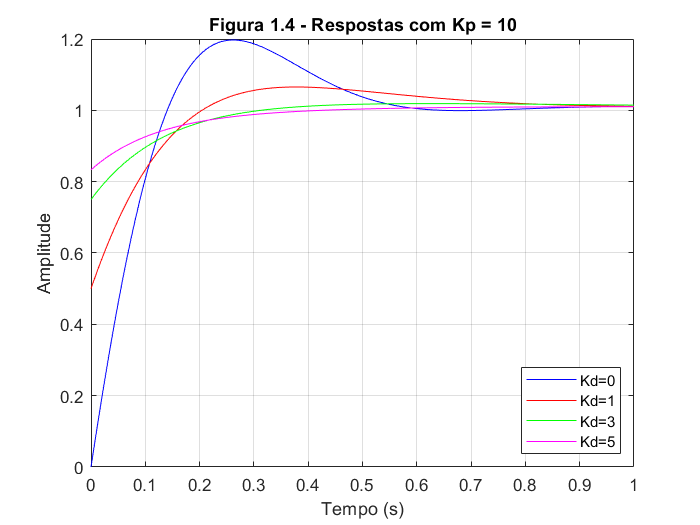

figure
plot(t,y1,'b',t,y2,'r',t,y3,'g',t,y4,'m')
grid on;
hold on;
title('Figura 1.4 - Respostas com Kp = 10')
xlabel('Tempo (s)')
ylabel('Amplitude')
ylim([0 1.2]);
yticks(0:0.2:1.2);
legend('Kd=0','Kd=1','Kd=3','Kd=5','Location','southeast'), hold all

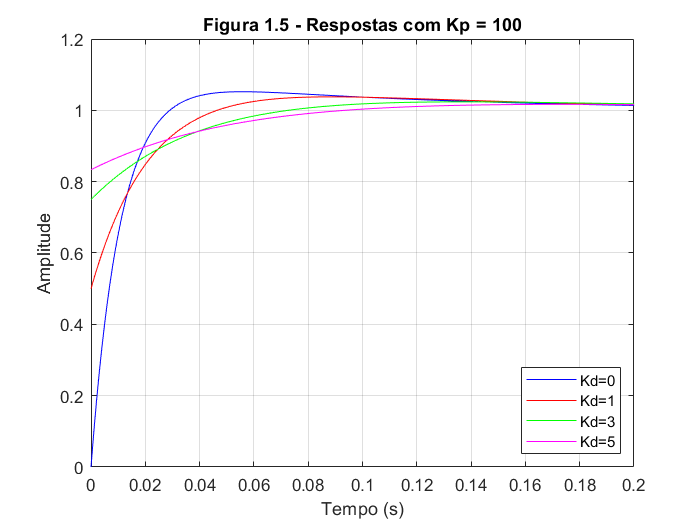


figure
plot(t,y5,'b',t,y6,'r',t,y7,'g',t,y8,'m')
grid on;
title('Figura 1.5 - Respostas com Kp = 100')
xlabel('Tempo (s)')
ylabel('Amplitude')
ylim([0 1.2]);
yticks(0:0.2:1.2);
xlim([0 0.2]);
legend('Kd=0','Kd=1','Kd=3','Kd=5','Location','southeast')

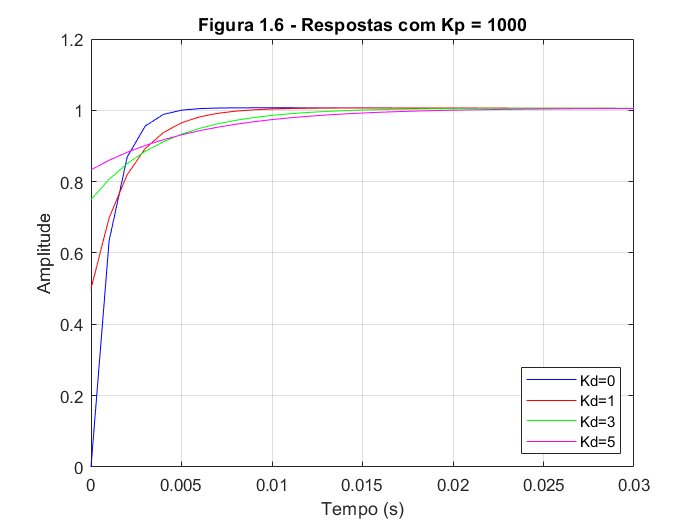


figure
plot(t,y9,'b',t,y10,'r',t,y11,'g',t,y12,'m')
grid on;
title('Figura 1.6 - Respostas com Kp = 1000')
xlabel('Tempo (s)')
ylabel('Amplitude')
ylim([0 1.2]);
yticks(0:0.2:1.2);
xlim([0 0.03]);
legend('Kd=0','Kd=1','Kd=3','Kd=5','Location','southeast')

Os critérios de sobressinal (OverShoot), tempo de subida (RiseTime) e tempo de estabelecimento (SettlingTime) estão dispostos na tabela 1.1 e na tabela 1.2  a avaliação do erro em regime. 

OS=0; RT=0; ST=0;
for k=1:1:12
    OS(k)=stepinfo(gmf(k)).Overshoot;
    RT(k)=stepinfo(gmf(k)).RiseTime;
    ST(k)=stepinfo(gmf(k)).SettlingTime;
end
Kp = [10; 10; 10; 10; 100; 100; 100; 100; 1000; 1000; 1000; 1000];
Kd = [0; 1; 3; 5; 0; 1; 3; 5; 0; 1; 3; 5];
OS=OS';
RT=RT';
ST=ST';
Tabela1=table(Kp, Kd, OS, RT, ST,'VariableNames',{'Kp','Kd','Sobressinal (%)','T. Subida (s)','T. Estabelecimento (s)'})

Tabela1 = 12×5 table
     Kp     Kd    Sobressinal (%)    T. Subida (s)    T. Estabelecimento (s)
    ____    __    _______________    _____________    ______________________
      10    0          19.718             0.1072              0.54013       
      10    1          6.5451            0.13179              0.78135       
      10    3          1.8814            0.10407              0.23639       
      10    5         0.99761           0.063293              0.24983       
     100    0          5.2229           0.018429               0.1617       
     100    1          3.7788           0.025762               0.1751       
     100    3          2.3751           0.026931              0.18497       
     100    5          1.6732           0.020887             0.067598       
    1000    0         0.63264          

disp('Tabela 1.1 - Valores de Sobressinal, Tempo de Subida e Tempo de Estabelecimento')

Tabela 1.1 - Valores de Sobressinal, Tempo de Subida e Tempo de Estabelecimento


erp_d=0; erp_r=0;
for k=1:1:12
    
    Kp=dcgain(gg(k)); % Calcula Kp=numg/deng para s=0
    erp_d(k)=1/(1+Kp);

    numg = gg(k).Numerator{1};
    deng = gg(k).Denominator{1};
    numsg=conv([1 0],numg); 
    densg=deng; 
    sG=tf(numsg,densg); 
    sG=minreal(sG);
    Kv=dcgain(sG); % Calcula Kv=sG(s) para s=0
    erp_r(k)=1/Kv;
end
Kp = [10; 10; 10; 10; 100; 100; 100; 100; 1000; 1000; 1000; 1000];
Kd = [0; 1; 3; 5; 0; 1; 3; 5; 0; 1; 3; 5];
erp_d=erp_d';
erp_r=erp_r';
Tabela2=table(Kp, Kd, erp_d, erp_r,'VariableNames',{'Kp','Kd','Erro em regime ao degrau','Erro em regime à rampa'})

Tabela2 = 12×4 table
     Kp     Kd    Erro em regime ao degrau    Erro em regime à rampa
    ____    __    ________________________    ______________________
      10    0                0                          0           
      10    1                0                          0           
      10    3                0                          0           
      10    5                0                          0           
     100    0                0                          0           
     100    1                0                          0           
     100    3                0                          0           
     100    5                0                          0           
    1000    0                0                          0           
    1000    1                0                          0           
    1000    3  

disp('Tabela 1.2 - Valores de Erro em regime ao degrau e à rampa')

Tabela 1.2 - Valores de Erro em regime ao degrau e à rampa


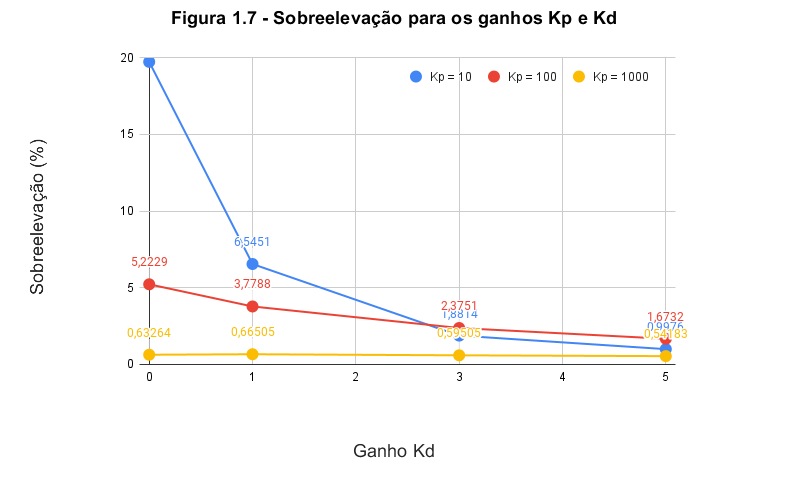

figure
imshow("UPPD.png")
title('Figura 1.7 - Sobreelevação para os ganhos Kp e Kd')
xlabel('Ganho Kd')
ylabel('Sobreelevação (%)')

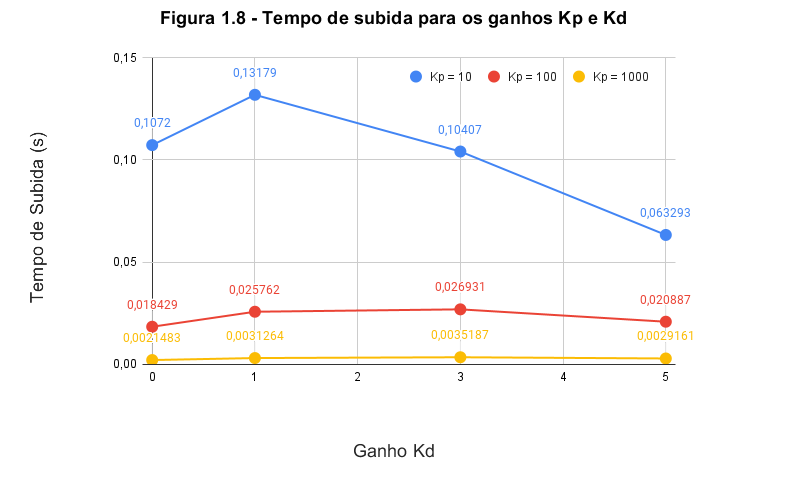

figure
imshow("trPD.png")
title('Figura 1.8 - Tempo de subida para os ganhos Kp e Kd')
xlabel('Ganho Kd')
ylabel('Tempo de Subida (s)')

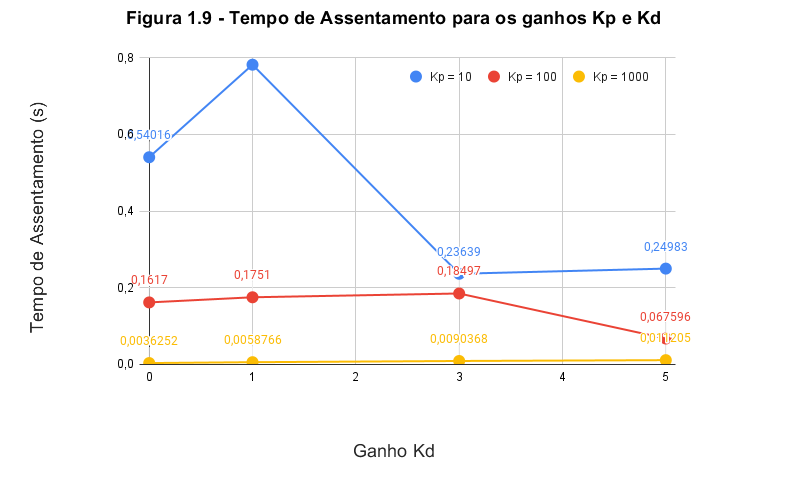

figure
imshow("tsPD.png")
title('Figura 1.9 - Tempo de Assentamento para os ganhos Kp e Kd')
xlabel('Ganho Kd')
ylabel('Tempo de Assentamento (s)')

### Conclusão

Escolher numericamente cada parâmetro é avaliar os pontos mais importantes para cada aplicação. Partindo de uma ideia onde devemos escolher um controlador P, PD ou PI, já podemos pela função de malha aberta não utilizar o PI pois é um controlador que pode zerar o erro a uma entrada em rampa, entretanto como mencionando anteriormente, a função de malha aberta é do tipo 2, isso elimina o erro a rampa. Fazendo-se não necessária a utilização do controlador PI. Fica provado com a tabela 1.2 do erro a entrada em rampa. 

Restando apenas os controladores P e PD, o controlador P nos permite uma resposta mais rápida com o aumento do ganho K, entretanto resta um sobressinal quando utilizado um controlador contendo apenas o ganho proporcional. Com isso, nos resta o controlador PD que permite uma resposta tão rápida quanto do controlador proporcional (e até mais rápida) com a capacidade de anular o sobressinal.

De acordo com os resultados acima, podemos observar claramente a tendência de resposta do sistema. Na figura 1.7 avaliamos a sobreelevação para cada valor testado de Kd em função da série que representa o ganho Kp e comparamos essas séries. À medida que o ganho Kp aumenta, a tendência é de uma sobreelevação menor, da mesma forma que para cada série de Kp, à medida que o ganho Kd aumenta a sobreelevação diminui, caracterizando um sistema PD. Quanto maior os ganhos Kp e Kd, menor a sobreelevação.

Assim como o sobressinal, os tempos de subida e de assentamento vão caindo à medida em que os ganhos vão aumentando. Entretanto, existe um ponto máximo quando Kd é igual à 1, para todas as séries (Kp=10 ou =100 ou =1000), ficando mais claro no ganho Kp igual a 10. A partir desse ponto de máximo, a tendência da resposta é diminuir o tempo de subida e de assentamento à medida que o Kd aumente.

Com essas declarações acima, o ideal seria estressar as simulações aos máximos valores de ganhos possíveis de serem implementados fisicamente avaliando o custo benefício (caso haja), pois o ganho de tempo e sobreelevação podem chegar a valores em que o ganho aumente muito e as respostas apesar de continuarem caindo não causem grande impacto no sistema.

Com isso escolhemos um controlador com ganho Kp = 100 e Kd = 5. Tais valores implicam em:

Sobreelevação: 1,6732%

Tempo de subida: 0,0208 s

Tempo de assentamento: 0,0675 s 

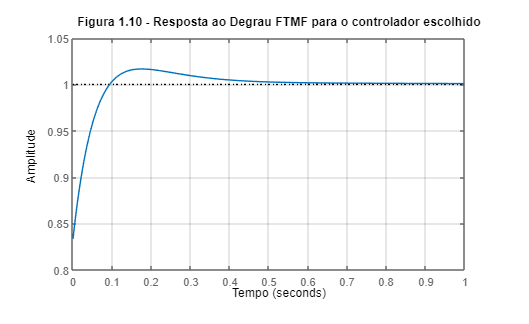

step(gmf(8),t)
grid on
title('Figura 1.10 - Resposta ao Degrau FTMF para o controlador escolhido')
ylabel('Amplitude')
xlabel('Tempo')

Tais parâmetros caracterizam de forma geral um bom controlador relativo a tempo de resposta e sobreelevação, além do erro em regime igual a zero, devido ao tipo de sistema.

## Projeto 1.2

O sistema de controle digital apresentado na figura 2.1 possui período de amostragem igual a 0,1 segundos e possui a função transferência da planta:


$$G_p(s)=\frac{Ne^{-(0,1N)s}}{Ns+10}$$


Considerando o controlador PI digital: 

$D(z) = k\frac{z-a}{z-1}$, 

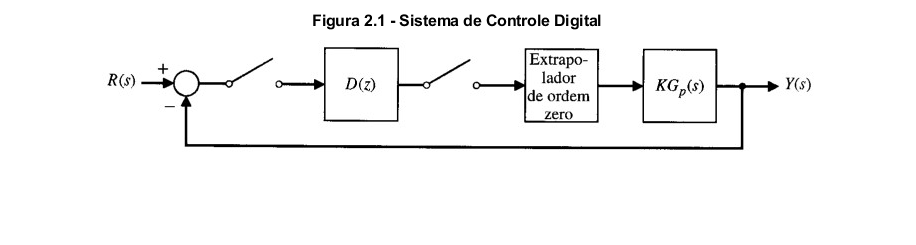

close all
figure
imshow("figuradorf.jpg")
title('Figura 2.1 - Sistema de Controle Digital')

clear
clc
format shortG
format compact
syms x
N = 11;

### **Condições de Projeto**

**Função de transferência com atraso**

Usando a aproximação de padé para o atraso de transporte $e^{-Ts}=\frac{1-Ts/2}{1+Ts/2}$, encontra-se a função de transferência no domínio z:


$$G_P {\left(s\right)}=\frac{N\frac{1-0,1Ns/2}{1+0,1Ns/2}}{\textrm{Ns}+10}$$


T = 0.1; % periodo de amostragem
t=0:T:50; % vetor tempo para simulações
gp_sym = (N*(1-0.1*N*x/2)/(1+0.1*N*x/2))/(N*x+10);
gp_sym = simplifyFraction(gp_sym);
[num_sym, den_sym] = numden(gp_sym);
gp = tf(sym2poly(num_sym),sym2poly(den_sym));
gpd = c2d(gp,T);
gpd2 = zpk(gpd) % modelo de polos e zeros

gpd2 =
 
   -0.078976 (z-1.201)
  ---------------------
  (z-0.9131) (z-0.8338)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



**Lugar das Raízes **

O Lugar das Raízes intercepta o eixo real em:

% Interseção do LR com o eixo real
Fo = -poly2sym(gpd.Denominator{1})/poly2sym(gpd.Numerator{1});
dFo = diff(Fo);
vpa(solve(dFo,'Real',true))

$$ans = \left(\begin{array}{c} 0.87583661750031447760645805703795\\ 1.5266005494476763181647885199993 \end{array}\right)$$

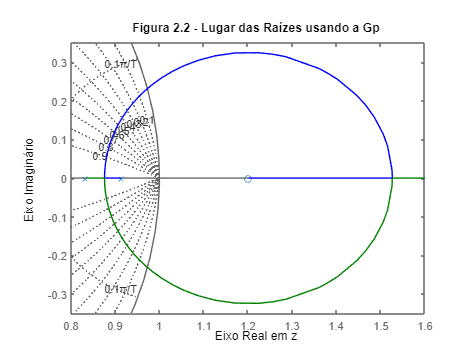

figure
rlocus(gpd)
grid on
title('Figura 2.2 - Lugar das Raízes usando a Gp')
ylabel('Eixo Imaginário')
xlabel('Eixo Real em z')
xlim([0.8 1.6])
ylim([-0.35 0.35])

Observando o Lugar das Raízes, percebemos que o sistema é estável para K < 2,5, pois a região pertence ao círculo unitário.

K = 1;
gmf=feedback(K*gpd,1);
y1=step(gmf,t);

### **Projeto do Controlador Digital PI**

**Condição 01 de projeto. Erro em regime à entrada rampa seja menor que 1**

O cálculo para erro em regime à entrada rampa em sistemas discretos é dado por:

$e_{ss}=\lim_{z \rightarrow 1}(1-z^{-1})\frac{R(z)}{1+G(z)}$, onde $R(z)=T_s\frac{z}{(z-1)^2}$

Como: 

$T_s=0,1s$ e $G(z)=D(z)G_p(z)=K\frac{z-a}{z-1}\frac{-0,078976(z-1,201)}{(z-0,9131)(z-0,8338)}$, 

tem-se que:


$$e_{ss}=\frac{0,1(1-0,9131)(1-0,8338)}{-K(1-a)0,078976(1-1,201)}<1$$


Para cancelar um polo positivo, podemos usar a = 0,9131 ou a = 0,8338:

$K > 1,06$ para $a=0,9131$

$K > 0,555$ para $a=0,8338$

Segundo o livro texto do Dorf 8ª Edição, é uma boa prática anular um dos pólos que se encontram no semiplano direito. Dessa forma, escolhe-se **a** para anular um dos pólos (**a = 0,9131).**

a = 0.9131;
PI_d = tf([1 -a],[1 -1],T);
Gma = PI_d * gpd;

**Lugar das Raízes Controlador PI com a=0,9131**

O Lugar das Raízes intercepta o eixo real em:

Fo = -poly2sym(Gma.Denominator{1})/poly2sym(Gma.Numerator{1});
dFo = diff(Fo);
vpa(solve(dFo,'Real',true))

$$ans = \left(\begin{array}{c} 0.92930699552958567671489712079277\\ 1.4731390365545808305916857305565 \end{array}\right)$$

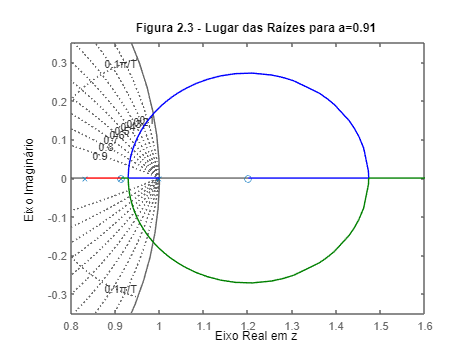

figure
rlocus(Gma)
grid on
title('Figura 2.3 - Lugar das Raízes para a=0.91')
ylabel('Eixo Imaginário')
xlabel('Eixo Real em z')
xlim([0.8 1.6])
ylim([-0.35 0.35]) % sistema estável para K < 1.75

**Ganho K**

Observando o Lugar das Raízes, percebemos que o sistema é estável para K < 1,75, pois a região pertence ao círculo unitário.

Considerando os cálculos anteriores para atender o erro a entrada à rampa e o o lugar das raízes, temos que a faixa de valores em que o K se encontra é 1,06 < K < 1,75.

**Simulação para diferentes valores de K**

Escolhe-se então valores de K dentro do intervalo 1,06 < K < 1,75.

K = 1.1;
ggd(1)=K*Gma;
gmf(1)=feedback(ggd(1),1);
y2=step(gmf(1),t);

K = 1.5;
ggd(2)=K*Gma;
gmf(2)=feedback(ggd(2),1);
y3=step(gmf(2),t);

K = 1.7;
ggd(3)=K*Gma;
gmf(3)=feedback(ggd(3),1);
y4=step(gmf(3),t);

Agora para verificar o controlador com outro valor de **a,** escolhe-se **a = 0.8338 **para anular o outro polo positivo. 

a = 0.8338;
PI_d = tf([1 -a],[1 -1],T);
Gma = PI_d * gpd;

**Lugar das Raízes Controlador PI com a=0,8338**

O Lugar das Raízes intercepta no eixo real em:

Fo = -poly2sym(Gma.Denominator{1})/poly2sym(Gma.Numerator{1});
dFo = diff(Fo);
vpa(solve(dFo,'Real',true))

$$ans = \left(\begin{array}{c} 0.96043653994686214571202123056407\\ 1.4420127557664244725532292851361 \end{array}\right)$$

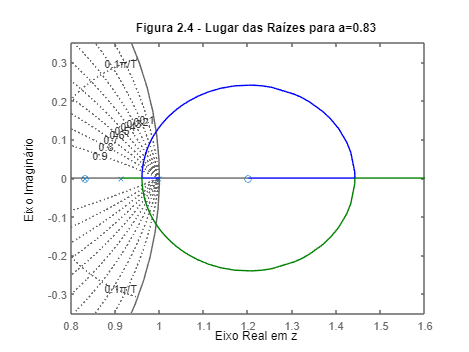

figure
rlocus(Gma)  % sistema estável para K < 0.9
grid on
title('Figura 2.4 - Lugar das Raízes para a=0.83')
ylabel('Eixo Imaginário')
xlabel('Eixo Real em z')
xlim([0.8 1.6])
ylim([-0.35 0.35])

**Ganho K**

Observando o Lugar das Raízes, percebemos que o sistema é estável para K < 0,9, pois a região pertence ao círculo unitário.

Considerando os cálculos anteriores para atender o erro a entrada à rampa e o o lugar das raízes, temos que a faixa de valores em que o K se encontra é 0,555 < K < 0,9.

**Simulação para diferentes valores de K**

Escolhe-se então valores de K dentro do intervalo 0,555 < K < 0,9.

K = 0.6;
ggd(4)=K*Gma;
gmf(4)=feedback(ggd(4),1);
y5=step(gmf(4),t);

K = 0.7;
ggd(5)=K*Gma;
gmf(5)=feedback(ggd(5),1);
y6=step(gmf(5),t);

K = 0.8;
ggd(6)=K*Gma;
gmf(6)=feedback(ggd(6),1);
y7=step(gmf(6),t);

### Resultados

Representação gráfica dos resultados das simulações e seus parâmetros tabulados.

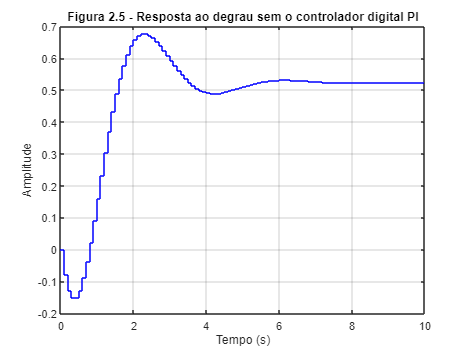

% Plots
figure
stairs(t,y1,'b');
hold on;
grid on;
title('Figura 2.5 - Resposta ao degrau sem o controlador digital PI')
xlim([0 10])
xlabel('Tempo (s)')
ylabel('Amplitude')

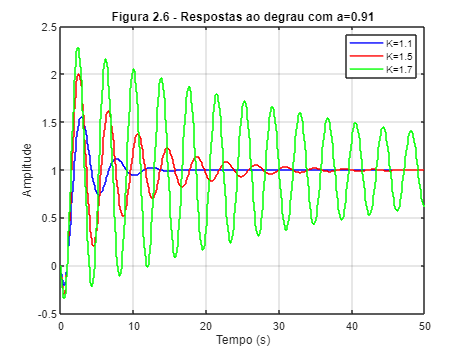

figure
stairs(t,y2,'b')
hold on;
grid on;
stairs(t,y3,'r')
stairs(t,y4,'g')
legend('K=1.1','K=1.5','K=1.7')
title('Figura 2.6 - Respostas ao degrau com a=0.91')
xlabel('Tempo (s)')
ylabel('Amplitude')

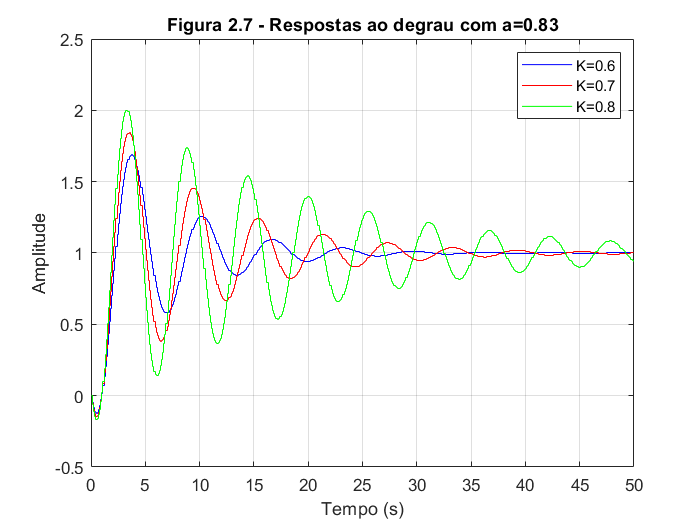

figure
stairs(t,y5,'b')
hold on;
grid on;
stairs(t,y6,'r')
stairs(t,y7,'g')
legend('K=0.6','K=0.7','K=0.8')
title('Figura 2.7 - Respostas ao degrau com a=0.83')
xlabel('Tempo (s)')
ylabel('Amplitude')

Os critérios de sobressinal (OverShoot), tempo de subida (RiseTime) e tempo de estabelecimento (SettlingTime) estão dispostos na tabela 2.1 e na tabela 2.2 a avaliação do erro em regime. 

% Tabelas
OS=0; RT=0; ST=0;

for k=1:1:6
    gg_c=d2c(ggd(k)); % Passando a função malha aberta em tempo discreto para o tempo contínuo
    gg_c=feedback(gg_c,1);
    OS(k)=stepinfo(gg_c).Overshoot;
    RT(k)=stepinfo(gg_c).RiseTime;
    ST(k)=stepinfo(gg_c).SettlingTime;
end
a = [0.9131; 0.9131; 0.9131; 0.8338; 0.8338; 0.8338];
K = [1.1; 1.4; 1.7; 0.6; 0.7; 0.8];
OS=OS';
RT=RT';
ST=ST';
Tabela1=table(a, K, OS, RT, ST,'VariableNames',{'a','K','Sobressinal (%)','T. Subida (s)','T. Estabelecimento (s)'})

Tabela1 = 6×5 table
      a        K     Sobressinal (%)    T. Subida (s)    T. Estabelecimento (s)
    ______    ___    _______________    _____________    ______________________
    0.9131    1.1        48.594            0.72981               10.572        
    0.9131    1.4        88.828            0.48478               20.531        
    0.9131    1.7        112.44            0.40358               42.704        
    0.8338    0.6        62.574              1.004               20.671        
    0.8338    0.7         76.68            0.85737               30.111        
    0.8338    0.8        91.341            0.73682               44.589        

disp('Tabela 2.1 - Valores de Sobressinal, Tempo de Subida e Tempo de Estabelecimento')

Tabela 2.1 - Valores de Sobressinal, Tempo de Subida e Tempo de Estabelecimento



erp_d=0; erp_r=0;
for k=1:1:6
    gg_c=d2c(ggd(k)); % Transforma gg para tempo continuo

    Kp=dcgain(gg_c); % Calcula Kp=numg/deng para s=0
    erp_d(k)=round(1/(1+Kp),8);

    numg = gg_c.Numerator{1};
    deng = gg_c.Denominator{1};

    numsg=conv([1 0],numg); 
    densg=deng; 
    sG=tf(numsg,densg); 
    sG=minreal(sG);
    Kv=dcgain(sG); % Calcula Kv=sG(s) para s=0
    erp_r(k)=1/Kv;
end

erp_d=erp_d';
erp_r=erp_r';
Tabela2=table(a, K, erp_d, erp_r,'VariableNames',{'a','K','Erro em regime ao degrau','Erro em regime à rampa'})

Tabela2 = 6×4 table
      a        K     Erro em regime ao degrau    Erro em regime à rampa
    ______    ___    ________________________    ______________________
    0.9131    1.1               0                       0.95103        
    0.9131    1.4               0                       0.69742        
    0.9131    1.7               0                       0.61537        
    0.8338    0.6               0                       0.91164        
    0.8338    0.7               0                       0.78141        
    0.8338    0.8               0                       0.68373        

disp('Tabela 2.2 - Valores de Erro em Regime ao degrau e à rampa')

Tabela 2.2 - Valores de Erro em Regime ao degrau e à rampa


### Conclusão

Analisado os resultados dos gráficos, considerando os dois valores de a, e as variações do ganho K dentro de suas faixas de estabilidade possíveis, a melhor combinação são valores de a=0,9131 e K=1,1.

Entretanto, apesar do sistema nos propor uma resposta estável e com erro em regime igual a zero, o controlador não tem boas características quanto a sobreelevação, tempo de subida e tempo de assentamento podendo fortemente inviabilizar dependendo da necessidade e do tipo de aplicação.

A sobreelvação mínima encontrada para as simulações testadas é de 55,78% muito alta para aplicações normais, assim como o tempo de assentamento de 12,8 segundos.

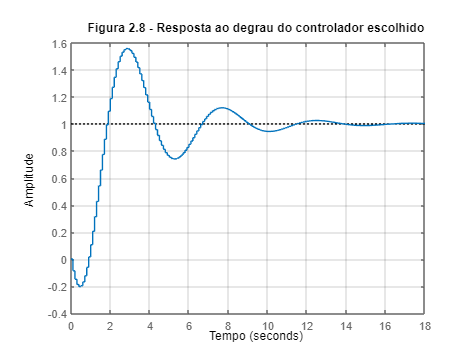

figure
step(gmf(1))
grid on
title('Figura 2.8 - Resposta ao degrau do controlador escolhido')
ylabel('Amplitude')
xlabel('Tempo')

A função de transferência de malha aberta com o controlador PI é definida abaixo.

zpk(ggd(1))

ans =
 
  -0.086874 (z-1.201) (z-0.9131)
  ------------------------------
   (z-1) (z-0.9131) (z-0.8338)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



## Projeto 1.3

Seja o braço do Robô Matutec, mostrado na Figura PA 10.8, pag 490 do livro do Dorf. Considere que a função de transferência em malha aberta (atuador+planta+sensor) deste robô seja dada por:


$$G_p \left(s\right)=\frac{10N}{\left(s+\frac{N}{\sqrt{N}}\right)\left(s+\sqrt{N}\right)\left(s+N\right)}$$


Verifique se é possível projetar um controlador PID usando o método do Lugar das Raízes, de maneira que o sobressinal à entrada degrau seja menor que 20%, e erro em regime à entrada rampa seja menor que 1 com o menor tempo de subida possível. Faça o projeto caso seja possível atender a esta especificação. Caso contrário explique com detalhes o motivo deste controlador não ser possível de atender a estes requisitos.

clear
clc
close all
format shortG
format compact
syms x
N = 11;

**Função de malha aberta inicial**

t=0:0.01:2;
nump = 10*N;
denp = conv(conv([1 N/sqrt(N)],[1 sqrt(N)]),[1 N]);
gp = tf(nump,denp);
gp_model = zpk(gp)

gp_model =
 
         110
  ------------------
  (s+11) (s+3.317)^2
 
Continuous-time zero/pole/gain model.



**Lugar das Raízes para ganho proporcional**

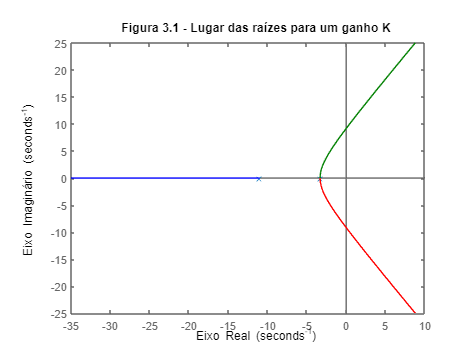

% rltool(gp)
figure 
rlocus(gp)
title('Figura 3.1 - Lugar das raízes para um ganho K')
ylabel('Eixo Imaginário')
xlabel('Eixo Real') 

### Condições de Projeto

**Condição 01 de projeto. Erro em regime à entrada rampa seja menor que 1**


$$K_v = \lim_{s \rightarrow 0}100 s\frac{K_{P2}+K_{I2}/s}{s^3+17,63s^2+83,96s+121}=\frac{100K_{I2}}{121}$$



$$e_{ss}=\frac{1}{Kv}=\frac{121}{100K_{I2}}<1$$



$$K_{I2}>1,21$$


**Condição 02 de projeto. Escolher valor de Z2**

Para escolher o valor de z2, deve-se lembrar que a parte real do polo mais próximo da origem é -3,317.

Dessa forma, adota-se $z_2=\frac{-K_{I2}}{K_{P2}}=-3,3$, já que está entre a origem e a parte real do pólo mais próximo da origem.

**Condição 03 de projeto. Verificar estabilidade com método de Routh**

Para verificar a estabilidade, utiliza-se o método do Diagrama de Roouth com a seguinte equação característica:


$$s^4+17,63s^3+83,96s^2+(121+110K_{P2})s+110K_{I2}=0$$


Substituindo $K_{I2}=-z_2K_{P2}=3,3K_{P2}$


$$s^4+17,63s^3+83,96s^2+(121+110K_{P2})s+110\cdot 3,3K_{P2}=0$$


Fazendo o Diagrama de Roouth, chegamos a seguinte inequação para verificar estabilidade:


$$-0,35K_{P2}^2+0,7K_{P2}+4,8>0$$



$$-2,84<K_{P2}<4,84$$


Ou seja, para $z_2=-3,3$, como $K_{P2}$ é positivo, temos que $0<K_{P2}<4,84$ para que o sistema seja estável.

Em resumo, o valor de $K_{P2}$ deve estar compreendido entre, $0,37<K_{P2}<4,84$ definidos pelas condições de valor de z2 adotado, pela estabilidade no método de Routh e pelo erro em regime de entrada à rampa.

**Função de malha aberda do controlador PI**

z2 = -3.3;              % obtido usando o LR para obter a resposta mais rápida e estável
numpi = [1 -z2];
denpi = [1 0];
gpi = tf(numpi,denpi)

gpi =
 
  s + 3.3
  -------
     s
 
Continuous-time transfer function.



**Simulação dos parâmetros para controlador PD**

Kp2 = 4.7;              %% Usando o maior valor para Kp2 possí­vel

numpi = Kp2*[1 -z2];
denpi = [1 0];
gpi = tf(numpi,denpi); % Função do controlador com Kd = 0

gg(1) = gpi * gp;
gmf(1)=feedback(gg(1),1);
y1=step(gmf(1),t);

% Projetando PD
num_sym = x*poly2sym(nump)*poly2sym(numpi);
den_sym = poly2sym(denpi)*poly2sym(denp)+poly2sym(nump)*poly2sym(numpi);
gma = zpk(tf(sym2poly(num_sym),sym2poly(den_sym))) % GMA linha

gma =
 
                517 s (s+3.3)
  -----------------------------------------
  (s+14.3) (s+3.3) (s^2 + 0.03544s + 36.16)
 
Continuous-time zero/pole/gain model.



**Lugar das Raízes a partir da GMA linha, a fim de avaliar ganhos Kd**

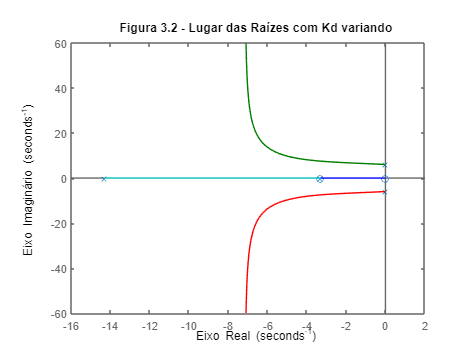

figure
rlocus(gma)
hold on;
title('Figura 3.2 - Lugar das Raízes com Kd variando')
ylabel('Eixo Imaginário')
xlabel('Eixo Real') 

Simulando o controlador PID em malha fechada p/ diferentes Kd1:

Kd1=0.2;
numpd = [Kd1 1];
numpid = conv(numpi,numpd);
denpid = denpi;
gc = tf(numpid,denpid);
gg(2) = gc * gp;
gmf(2)=feedback(gg(2),1);
y2=step(gmf(2),t);

Kd1=0.5; 
numpd = [Kd1 1];
numpid = conv(numpi,numpd);
denpid = denpi;
gc = tf(numpid,denpid);
gg(3) = gc * gp;
gmf(3)=feedback(gg(3),1);
y3=step(gmf(3),t);

Kd1=0.8; 
numpd = [Kd1 1];
numpid = conv(numpi,numpd);
denpid = denpi;
gc = tf(numpid,denpid);
gg(4) = gc * gp;
gmf(4)=feedback(gg(4),1);
y4=step(gmf(4),t);

%% Reduzindo Kp2 para que o PD  consiga reduzir o sobressinal atendendo especificaÃ§Ã£o


Um novo Kp2 foi definido, para adequar o melhor tempo de subida à uma sobreelvação menor que 20%. Considerando as mesmas variações em Kd1 a fim de realizar comparações.

Kp2 = 3;

numpi = Kp2*[1 -z2];
denpi = [1 0];
gpi = tf(numpi,denpi);

gg(5) = gpi * gp;
gmf(5)=feedback(gg(5),1);
y5=step(gmf(5),t);

% Projetando PD para o novo Kp
num_sym = x*poly2sym(nump)*poly2sym(numpi);
den_sym = poly2sym(denpi)*poly2sym(denp)+poly2sym(nump)*poly2sym(numpi);
gma = tf(sym2poly(num_sym),sym2poly(den_sym));

% rltool(gma)

% Simulando o controlador PID em malha fechada p/ diferentes Kd1
Kd1=0.2; 
numpd = [Kd1 1];
numpid = conv(numpi,numpd);
denpid = denpi;
gc = tf(numpid,denpid);
gg(6) = gc * gp;
gmf(6)=feedback(gg(6),1);
y6=step(gmf(6),t);

Kd1=0.5; 
numpd = [Kd1 1];
numpid = conv(numpi,numpd);
denpid = denpi;
gc = tf(numpid,denpid);
gg(7) = gc * gp;
gmf(7)=feedback(gg(7),1);
y7=step(gmf(7),t);

Kd1=0.8; 
numpd = [Kd1 1];
numpid = conv(numpi,numpd);
denpid = denpi;
gc = tf(numpid,denpid);
gg(8) = gc * gp;
gmf(8)=feedback(gg(8),1);
y8=step(gmf(8),t);

### Resultados

Representação gráfica dos resultados das simulações e seus parâmetros tabulados.

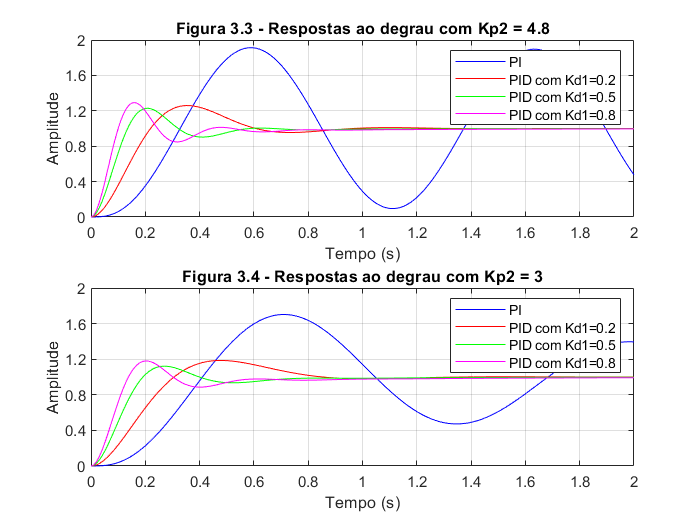

figure
subplot(2,1,1)
plot(t,y1,'b',t,y2,'r',t,y3,'g',t,y4,'m')
grid on;
title('Figura 3.3 - Respostas ao degrau com Kp2 = 4.8')
yticks(0:0.4:2)
xlabel('Tempo (s)')
ylabel('Amplitude')
legend('PI','PID com Kd1=0.2','PID com Kd1=0.5','PID com Kd1=0.8')

subplot(2,1,2)
plot(t,y5,'b',t,y6,'r',t,y7,'g',t,y8,'m')
grid on;
title('Figura 3.4 - Respostas ao degrau com Kp2 = 3')
yticks(0:0.4:2)
xlabel('Tempo (s)')
ylabel('Amplitude')
legend('PI','PID com Kd1=0.2','PID com Kd1=0.5','PID com Kd1=0.8')

Os critérios de sobressinal (OverShoot), tempo de subida (RiseTime) e tempo de estabelecimento (SettlingTime) estão dispostos na tabela 3.1 e na tabela 3.2 a avaliação do erro em regime.

OS=0; RT=0; ST=0;
for k=1:1:8
    OS(k)=stepinfo(gmf(k)).Overshoot;
    RT(k)=stepinfo(gmf(k)).RiseTime;
    ST(k)=stepinfo(gmf(k)).SettlingTime;
end
Kp = [4.8; 4.8; 4.8; 4.8; 3; 3; 3; 3;];
Kd = [0; 0.2; 0.5; 0.8; 0; 0.2; 0.5; 0.8];
OS=OS';
RT=RT';
ST=ST';
Tabela1=table(Kp, Kd, OS, RT, ST,'VariableNames',{'Kp','Kd','Sobressinal (%)','T. Subida (s)','T. Estabelecimento (s)'})

Tabela1 = 8×5 table
    Kp     Kd     Sobressinal (%)    T. Subida (s)    T. Estabelecimento (s)
    ___    ___    _______________    _____________    ______________________
    4.8      0        91.291            0.18979               215.86        
    4.8    0.2        25.938            0.14922              0.87372        
    4.8    0.5        22.897           0.090938              0.53787        
    4.8    0.8        29.293           0.067546              0.73627        
      3      0        70.235            0.24226               8.4456        
      3    0.2        18.597            0.20865               1.0484        
      3    0.5         12.17             0.1287              0.72508        
      3    0.8        18.104           0.093111               1.2009        

disp('Tabela 3.1 - Valores de Sobressinal, Tempo de Subida e Tempo de Estabelecimento')

Tabela 3.1 - Valores de Sobressinal, Tempo de Subida e Tempo de Estabelecimento



erp_d=0; erp_r=0;
for k=1:1:8
    
    Kp=dcgain(gg(k)); % Calcula Kp=numg/deng para s=0
    erp_d(k)=1/(1+Kp);

    numg = gg(k).Numerator{1};
    deng = gg(k).Denominator{1};
    numsg=conv([1 0],numg); 
    densg=deng; 
    sG=tf(numsg,densg); 
    sG=minreal(sG);
    Kv=dcgain(sG); % Calcula Kv=sG(s) para s=0
    erp_r(k)=1/Kv;
end
Kp = [4.8; 4.8; 4.8; 4.8; 3; 3; 3; 3;];
Kd = [0; 0.2; 0.5; 0.8; 0; 0.2; 0.5; 0.8];
erp_d=erp_d';
erp_r=erp_r';
Tabela2=table(Kp, Kd, erp_d, erp_r,'VariableNames',{'Kp','Kd','Erro em regime ao degrau','Erro em regime à rampa'})

Tabela2 = 8×4 table
    Kp     Kd     Erro em regime ao degrau    Erro em regime à rampa
    ___    ___    ________________________    ______________________
    4.8      0               0                       0.070922       
    4.8    0.2               0                       0.070922       
    4.8    0.5               0                       0.070922       
    4.8    0.8               0                       0.070922       
      3      0               0                        0.11111       
      3    0.2               0                        0.11111       
      3    0.5               0                        0.11111       
      3    0.8               0                        0.11111       

disp('Tabela 3.2 - Valores de Erro em regime ao degrau e à rampa')

Tabela 3.2 - Valores de Erro em regime ao degrau e à rampa


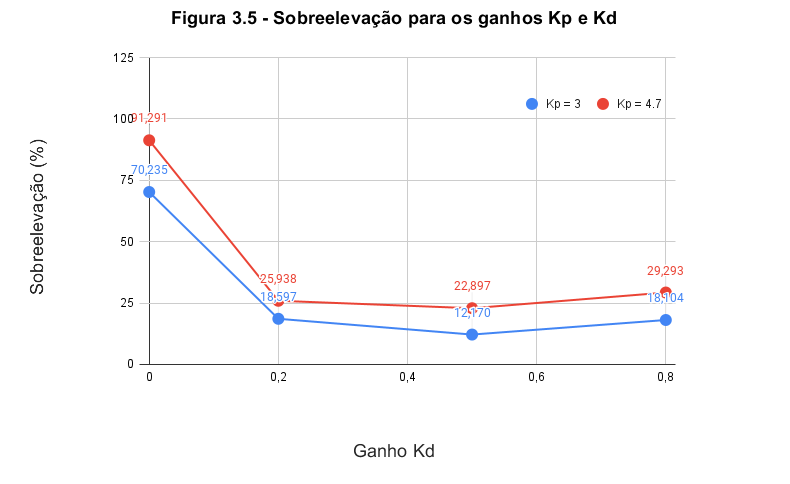


figure
imshow("UPPID.png")
title('Figura 3.5 - Sobreelevação para os ganhos Kp e Kd')
xlabel('Ganho Kd')
ylabel('Sobreelevação (%)')

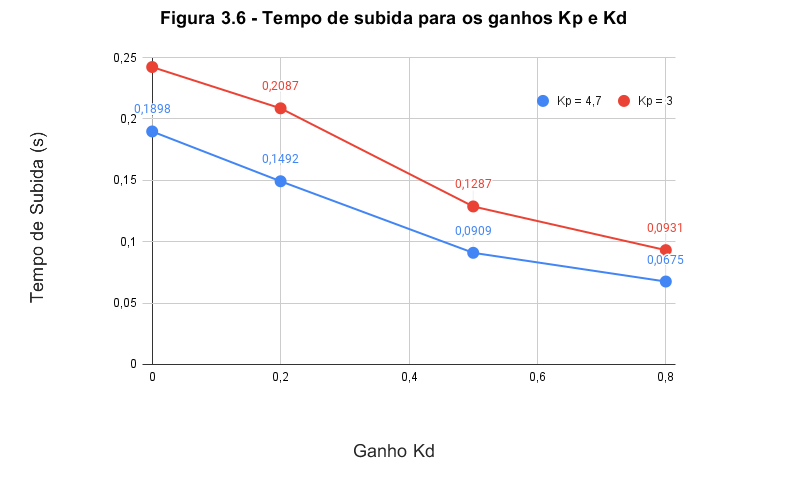

figure
imshow("trPID.png")
title('Figura 3.6 - Tempo de subida para os ganhos Kp e Kd')
xlabel('Ganho Kd')
ylabel('Tempo de Subida (s)')

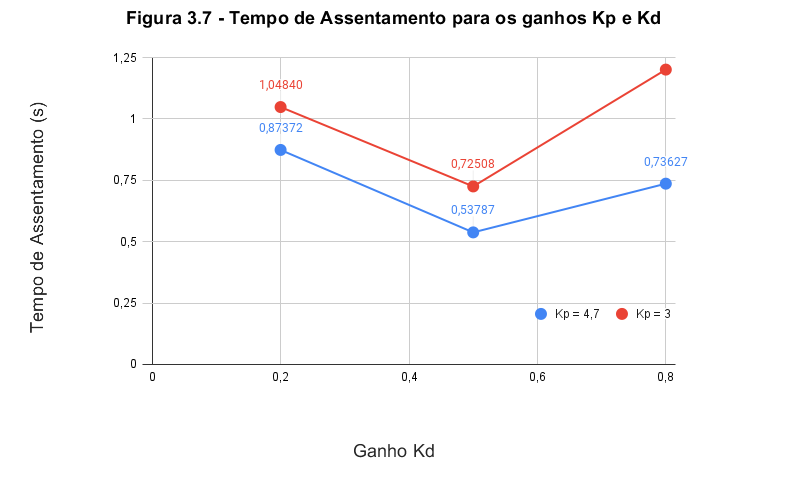

figure
imshow("tsPID.png")
title('Figura 3.7 - Tempo de Assentamento para os ganhos Kp e Kd')
xlabel('Ganho Kd')
ylabel('Tempo de Assentamento (s)')

### Conclusão

O controlador escolhido foi com $K_{P2}=3$, $K_{D1}=0.8$ e $K_{I2}=9.9$, pois  $z_2=-3.3=-K_{I2}/K_{P2}$.

Sabe-se que


$$G_C(s)=(1+K_{D1}s)(K_{P2}+K_{I2}/s)=(K_{P2}+K_{D1}K_{I2})+K_{D1}K_{P2}s+K_{I2}/s$$


Escrevendo Gc em função de $K_P,K_D,K_I$:


$$G_C(s)=K_P+K_Ds+K_I/s$$



$$G_C(s)=10.92+2.4s+9.9/s$$


Comprovando, o valor de gc para os valores de constantes escolhidas:

gc

gc =
 
  2.4 s^2 + 10.92 s + 9.9
  -----------------------
             s
 
Continuous-time transfer function.



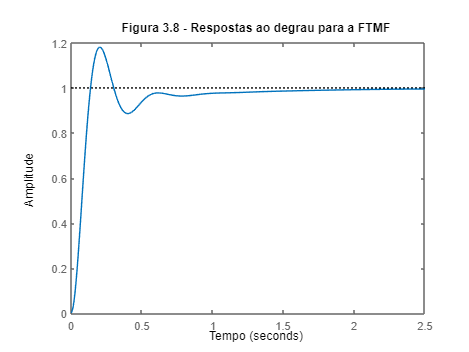

figure
step(gmf(8))
hold on;
title('Figura 3.8 - Respostas ao degrau para a FTMF')
ylabel('Amplitude')
xlabel('Tempo')

stepinfo(gmf(8))

ans = struct with fields:
         RiseTime: 0.093111
    TransientTime: 1.2009
     SettlingTime: 1.2009
      SettlingMin: 0.88616
      SettlingMax: 1.181
        Overshoot: 18.104
       Undershoot: 0
             Peak: 1.181
         PeakTime: 0.2027

Os resultados acima mostram os detalhes da resposta em malha fechada da equação escolhida, tanto para sobreelevação menor que 20%, tempo de subida menor possível e erro estacionário sob entrada em rampa menor que 1.

Os três gráficos nos resultados mostrados nas figuras 3.5, 3.6 e 3.7 comparam as séries para Kp = 3 e Kp = 4,7 em função dos parâmetros de resposta (sobreelevação, tempo de subida e tempo de assentamento respectivamente) com os ganhos Kd escolhidos.

Avaliando o primeiro, que trata a sobreelevação, fica evidente que um ganho proporcional menor (Kp) nos entrega uma menor sobreelevação, visto que a série Kp=3 fica abaixo da série Kp=4,7. Partindo para os dois próximos gráficos em que são avaliados os tempos de subida e assentamento, o comportamento é inverso, à medida que ganho proporcional aumenta os tempos de subida e assentamento diminuem.

Foi escolhido um controlador cuja máxima ultrapassagem fosse menor que 20% e com o menor tempo de subida entre os parâmetros de ganho derivativo, o qual possui Kp = 3 e Kd = 0,8. Este apresenta um sobressinal de 18,104%, um tempo de subida de 0,0931 s e um tempo de estabelecimento de 1.2 s. Apesar de ter um sobressinal e um tempo de estabelecimento maior que o controlador com Kp = 3 e Kd = 0,5, ele possui um tempo de subida menor e as especificações de projeto pedem que o controlador tenha uma sobrelevação menor que 20% e menor tempo de subida possível.

É interessante observar que na figura 3.5 há uma diferença grande entre os valores de sobressinal de Kd = 0 e para Kd = 0.2 com Kp=4.8, assumindo os valores de 91,29% e 25,94% respectivamente. Isso mostra que o simples fato de incluir o ganho derivativo ao controlador, por menor que seja seu valor, a redução do sobressinal é consideravelmente alta.

A tabela 3.2 trata o erro estacionário e, como projetado, nenhum controlador rompeu o limite de 1. Isso mostra que os cálculos feitos para estipular intervalos válidos de Kp para que fossem atendidas as especificações de projeto estavam certos. Dessa forma, temos um controlador PID atendendo as condições de sobressinal, tempo de subida e erro em regime.